# **MATLAB**

## MATLAB (MATrix LABoratory) is a high-level programming language and interactive environment for algorithm development, data visualization, data analysis, and numeric computation. Core strengths of the system include rapid development, powerful built-in functionality and extensive application-specific functionality provided by both official toolboxes and user-contributed code.

## MATLAB contains several different parts:

- **Desktop Tools and Development Environment** **-** This part of MATLAB is the set of tools and facilities that help you use and become more productive with MATLAB functions and files. Many of these tools are graphical user interfaces. It includes: the MATLAB desktop and Command Window, an editor and debugger, a code analyzer, and browsers for viewing help, the Workspace, and folders.

- **Mathematical Function Library -** This library is a vast collection of computational algorithms ranging from elementary functions, like sum, sine, cosine, and complex arithmetic, to more sophisticated functions like matrix inverse, matrix eigenvalues, and fast Fourier transforms.

- **The Language -** The MATLAB language is a high-level matrix/array language with control flow statements, functions, data structures, input/output, and object-oriented programming features. It allows both "programming in the small" to rapidly create quick programs you do not intend to reuse. You can also do "programming in the large" to create complex application programs intended for reuse.

- **Graphics -** MATLAB has extensive facilities for displaying vectors and matrices as graphs, as well as annotating and printing these graphs. It includes high-level functions for two-dimensional and three-dimensional data visualization, image processing, animation, and presentation graphics. It also includes low-level functions that allow you to fully customize the appearance of graphics as well as to build complete graphical user interfaces on your MATLAB applications.

- **External Interfaces -** The external interfaces library allows you to write C and Fortran programs that interact with MATLAB. It includes facilities for calling routines from MATLAB (dynamic linking), for calling MATLAB as a computational engine, and for reading and writing MAT-files.

# **References**

## **A MATLAB Tutorial -  **[https://people.math.osu.edu/overman.2/matlab.pdf](https://people.math.osu.edu/overman.2/matlab.pdf)

## **        Ed Overman, Department of Mathematics, The Ohio State University**

## **Introduction to MATLAB for engineering students - **[http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf](http://www.mccormick.northwestern.edu/docs/efirst/matlab.pdf)

## **       David Houcque, Northwestern University**

## **An Introduction to  Statistical Learning (Advertising data) - **[http://www-bcf.usc.edu/~gareth/ISL](http://www-bcf.usc.edu/~gareth/ISL)

## **       Gareth James, Daniela Witten, Trevor Hastie and Robert Tibshirani   **

# **Summary**

- **Desktop tools and development environment**

- **Definitions: Matrices and Vectors**

- **Matlab data types**

- **Scalar calculations**

- **Variables**

- **Script M-files**

- **Functions**

- **Vectors**

- **Matrices**

- **Basic plotting**

# **Desktop Tools and Development Environment**

demo % access Matlab's demonstration page
help plot % obtain help in the command window
doc plot % access the online browser in reference to the plot command
lookfor plot % obtain all potential Matlab functions associated with 'plot
who % display existing workspace variables 
whos % the same as who but display additional information
clc % clears the screen

# 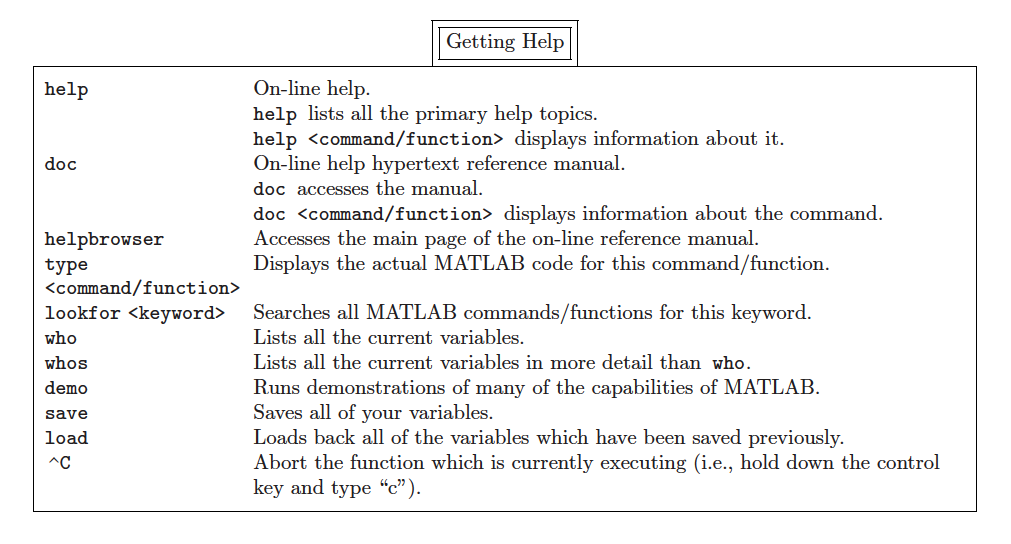

# **Definitions: Matrices and Vectors**

- `The most basic MATLAB data structure is the matrix: a two-dimensional, rectangular structure capable of storing multiple elements of data in an easily accessible format.`

- `The elements of a matrix must all be of the same data type (numeric, character, logical etc.), but here we will focus on numeric matrices.`

- `MATLAB uses two-dimensional matrices to store single elements and linear series of elements as well. In these cases, the dimensions are 1-by-1 and 1-by-N (or N-by-1) respectively. For numeric data, special meaning is sometimes attached to 1-by-1 matrices, which are scalars, and to matrices with only one row or column, which are vectors.`

- `MATLAB also supports data structures that have more than two dimensions. These data structures are referred to as multidimensional arrays, and indeed the matrix is really a special case of an n-dimension array, with n=2.`

# **MatLab data types**

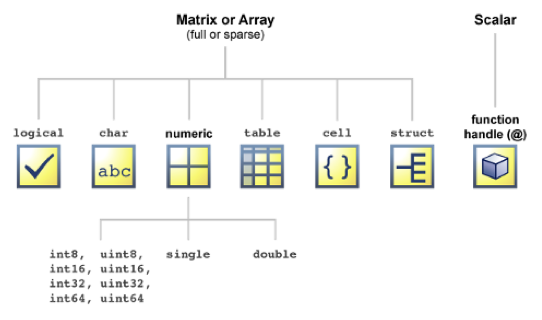

[http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html](http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)

# **Scalar Calculations**

## **Simple Arithmetical Operations**

MATLAB can be used as a scientific calculator:

14*2+2/2

2^0 % use ^ for exponentiation
2^1
2^20

2*10^-1
2e-1 % use e for scientific notation (e or E replaces *10^ in the numeric value)
2E-1
2.e-1
2.E-1

e-1 % this should produce an error because you have to have a digit before the symbol e
1e-1


# **Variables**

x = 2 % assigns variable x to 2
x
x;
fx = 3*x^6 - 17*x^3+79 % Matlab evaluates x in the expression on the right and assigns the outcome value to a new variable fx
x = 2^(1/3); fx = 3*x^6 - 17*x^3 + 79; g = 3/fx; % makes three assignments to variables in one single line of code (this is not very good for readibility)
x = 2^(1/3), fx = 3*x^6 - 17*x^3 + 79, g = 3/fx
x = x+5 % adds 5 to the value of x and updates x
x
clear % clears the workspace

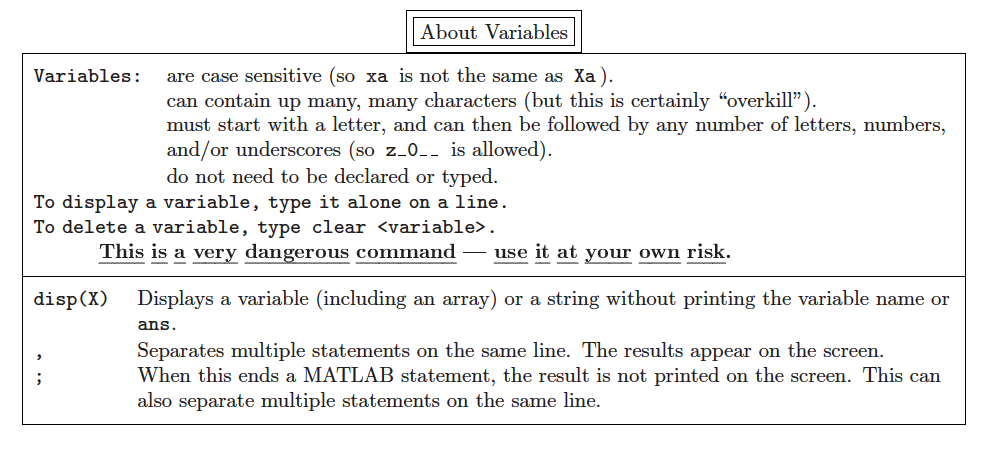

There are reserved names/words, called keywords:

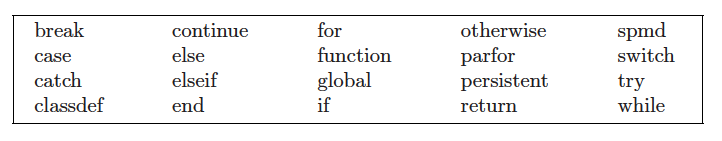

...as well as predefined variables:

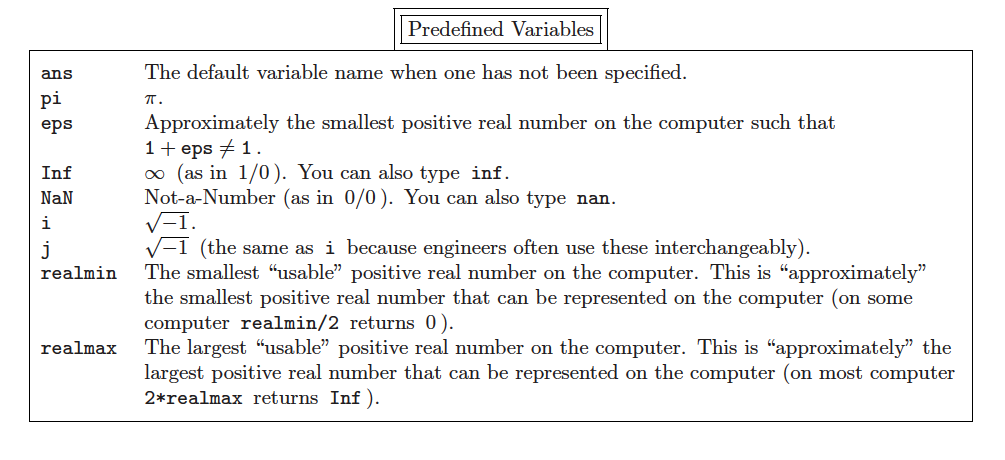

a=1/3
format long % changes the display format to maximum precision (values do not actualy change, just how they are displayed)
a
format short
a

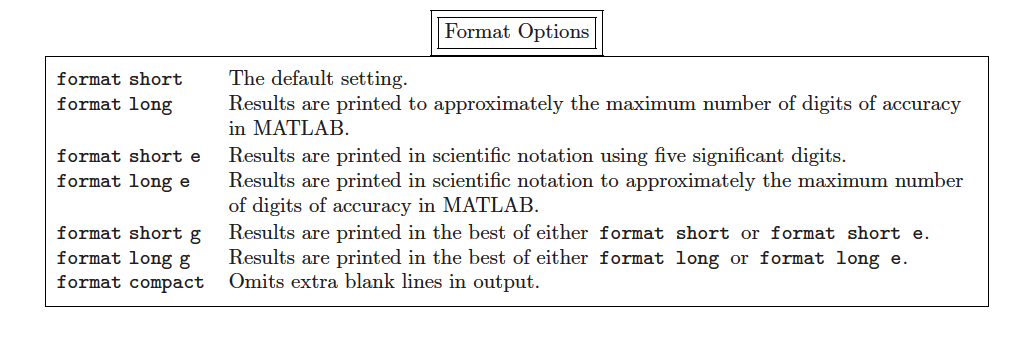

clear
who
diary % saves command window text to file
a=5
b=10
c=a*b
diary off % toggles the switch off so that following commands will not be saved into the file
save a b % save variables a b in a .mat Matlab's binary file
clear
who
save('vars','a','b') % save variables a b in a vars.mat Matlab's binary file
clear
who
load('vars') % load the variables in the binary vars.mat file into the workspace


# **Script M-files**

edit workshop.m % open Matlab's editor (include any commands in the file and save it)
workshop % run the script file (the extension is not included)

- The name of the file includes the extension ".m", i.e., "<file name>.m", but you execute it in MATLAB by typing <file name>, i.e., without the extension.

- The file name can consist of (almost any number of) letters (lowercase and/or uppercase), numbers, and underscores, i.e. "_".

- The first character must be a letter.

- Spaces are not allowed.

- Make sure your file name is not the same as one of MATLAB's commands/functions.

type workshop % displays the content of the file

# **Functions**

## **Functions are programs (or routines) that accept input arguments and return output arguments. Each M-file function (or function or M-file for short) has its own area of workspace, separated from the MATLAB base workspace.**

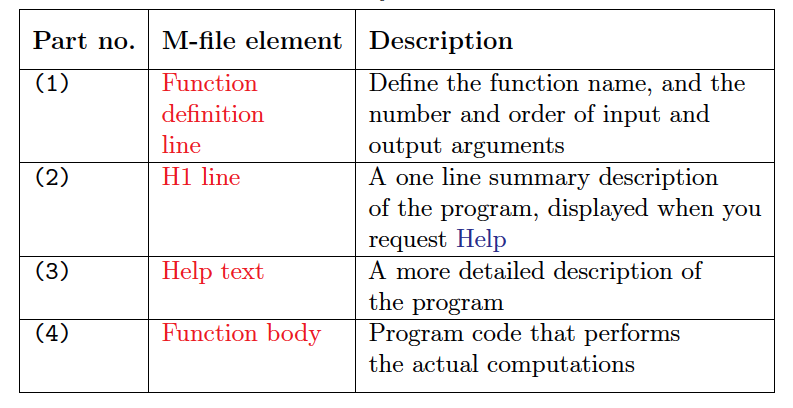

**function [outputs] = function_name(inputs)**

**    body**

**end**

**Examples of headers:**

-     function C=FtoC(F)

-     function area=TrapArea(a,b,h)

-     function [h,d]=motion(v,angle)

% Define a function that calculates the factorial of a number n

## **Scripts vs Functions**

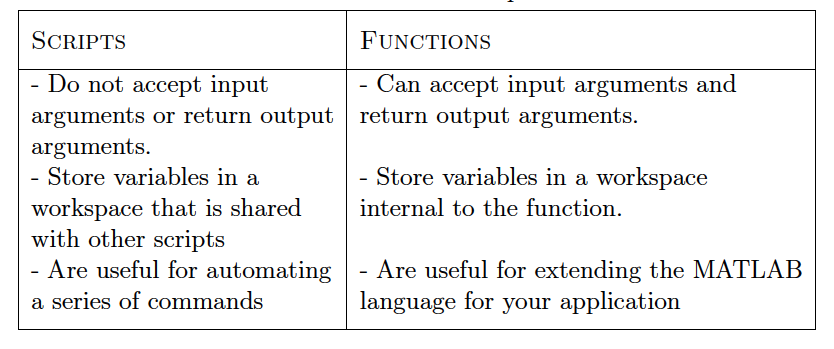

# **Vectors**


clear
who
x=[3 2 4 7 5] % creates a row vector x with 5 elements
x=[3,2,4,7,5] % creates a row vector x with 5 elements 
y=[3;2;4;7;5] % creates a column vector y with 5 elements

x(1) % access the first element of the vector
x(0) 
x(6)
x(3)

y=1:5 % creates a row vector y with 5 elements from 1 to 5
y=1:5'
y=(1:5)' % ' is used to transpose the vector y - creates a column vector

x=1:5
x=1:2:10 % creates a row vector with every other elemens from 1 to 10

x1=linspace(1,10,5); % creates a vector with 5 elements from 1 to 10
y1=x1(3:4) % slices vector x1 to obtain the third and fourth elements of x1 and assigns to y1
y1(2)=3 % modifies the second value of y1 to 3
x1
y1(5)=4

x=[3 5]
x=[x x] % concatenates vector x with vector x 

x=1:5
x+x % sums vectors, add elements at the same index on both vectors
x=x+x

x=1:5
x=x*0.5 % multiply each element of the vector by 1/2

y=1:5
x+y

x*y
x.*y % multiply each element of the vectors x and y
x*y % obtains a scalar, product of the two vectors 

x=10:-2:0 % creates a vector from 10 to 0 with a negative step of -2
x=7:4 % this should produce an empty vector since the step = 1 by default

x=1:10;
max(x) % obtains maximum value of the vector
min(x) % obtains minimum value 
sum(x) % obtains the sum of the values 
prod(x) % obtains the product of elements 
mean(x) % obtains the mean 
std(x) % obtains the standard deviation

x=[1 23 5 17 8 3]
x<4 % evaluates this condition for each element of vector x, it returns a boolean index of the same length as vector x
x(x<4) % gets values x lower than 4

# **Matrices**


clear
who
[7 -2 +5], [7 - 2 + 5], [7, - 2, +5]

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1] % creates a 4 by 4 matrix with the specified elements, use semicolon for a new line
B = [6 3 2 8; 5 1 3]
ones(2,5) % creates a matrix of ones with 2 lines and 5 columns
zeros(2,2) % creates a matrix of zeros with 2 lines and 2 columns
rand(2,2) % creates a 2x2 matrix with random uniform numbers from 0 to 1

A = [1 2;3 4]
B = [5 6;7 8]

A+B % sums the two matrices
A-B
C=[A,B] % concatenates horizontaly the two matrices
D=[A;B] % concatenates vertically the two matrices

B = [5 6;7 8;9 10]
C=[A,B]
D=[A;B]

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]
A(3,2) % obtains the value of matrix A in the third line, second column
A(7) % obtain the same value of matrix A using linear indexing
linearindex = sub2ind(size(A),3,2) % obtain the linear indexing from the line/column indexing
[X,Y] = ind2sub(size(A),5) % obtain the line/column indexing from the linear indexing

A(2,1:3) % obtains the entire second line of matrix A
A(1:3:16)
A(2:3,1:3)

A(2,2:end)
A(2,:)
A([1,4,9])

L = A<5 % evaluates the condition for each element of matrix A
A(L) % obtains values of A lower than 5
A(A<5)
A(L) = 0 % assigns all values lower than 5 to 0 in matrix A

size(A)
length(A)
numel(A)

islogical(A) % checks whether A is a matrix of logical values
isnumeric(A) % checks whether A is a matrix of numeric values

isvector(A)
isscalar(A)
ismatrix(A)
isempty(A)

F = [1,2,3;4,5,6];
F(1,5)
F(1,5)=3

F = [1,2,3;4,5,6];
F(1:2,5:6) = 8
F(:,6) = [] % removes the sixth colum of matrix F

F = [1,2,3;4,5,6]
transpose(F) % tranposes matrix F
reshape(F,3,2) % reshapes matrix F into a matrix with 3 lines and 2 columns

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]
sort(A,1) % sort matrix A along the first dimension
sort(A,2) % sort matrix A along the second dimension

sort(A,2,'descend') % sort matrix A along the second dimension, from the highest to the lowest value
sortrows(A,2) % sort the matrix A according to the second column, maintaining dependence between columns of the matrix

max(A)
max(A,[],2) % obtains the maximum value of each line of matrix A 
[y,I]=max(A,[],2) % obtains the maximum values of matrix A in y and the indexes on I

mean(A,1) % obtains mean along the first dimension (number of columns is invariant)
mean(A,2) % obtains mean along the second dimension (number of lines is invariant)

sum(A(1,:))/length(A(1,:))
sum(A(2,:))/length(A(2,:))

## **There are many more operations on matrices. Here are a few of them:**

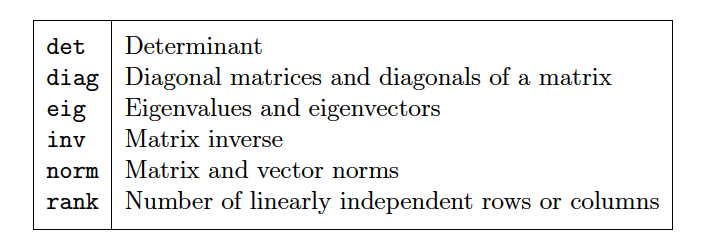

# **Basic plotting**

## **The basic MATLAB graphing procedure, for example in 2D, is to take a vector of x-coordinates, x = (x1; ... ; xN), and a vector of y-coordinates, y = (y1; ... ; yN), locate the points (xi; yi), with i = 1; 2; ... ; n and then join them by straight lines. You need to prepare x and y in an identical array form; namely, x and y are both row arrays or column arrays of the same length.**

clear

x = 0:pi/10:2*pi;
y1 = 2*cos(x);
y2 = cos(x);
y3 = 0.5*cos(x);
plot(x,y1,'--rs',x,y2,'-gd',x,y3,':bo',... % plots the three functions in one single figure
       'LineWidth',2,...
       'MarkerEdgeColor','k',...
       'MarkerSize',10)
   
xlabel('0 \leq x \leq 2\pi') % sets the label for the x axis
ylabel('Cosine functions') % sets the label for the y axis
legend('2*cos(x)','cos(x)','0.5*cos(x)') % sets the legend
title('Typical example of multiple plots') % sets the title
axis([0 2*pi -3 3]) % sets both axis range